Predict the proportions for the color

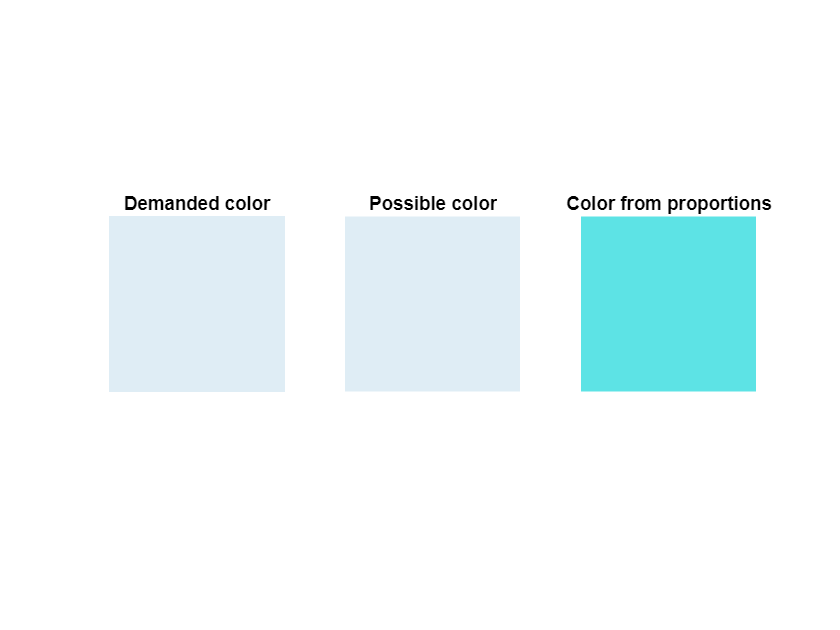

tablename = 'ModelTable600_.xls';
Ycell = cell(1,4); % 0 1 2 3 = MY1 MY2 CY CM
Wcell = cell(1,4);

for i = 1:4
    M1 = readmatrix(tablename,'Sheet',i);
    Ycell{i} = M1(:,1:3);
    Wcell{i} = M1(:,4:6);
end

%create HSV color
H = 0.56;
S = 0.09;
V = 0.96;

%convert to RGB
rgbcol = hsv2rgb([H S V]);
for i = 1:4
    M1 = Ycell{i};
    [n,~] = size(M1);
    M2 = M1;
    for j = 1:n
        M2(j,:) = hsv2rgb(M1(j,:));
    end
    Ycell{i} = M2;
end

[props, cls, rgbnew] = PredictProportions(rgbcol,Ycell,Wcell);
col8 = prop2pp(props,cls);

[rgb2,props2] = col82hsv(col8,Wcell,Ycell);
strcol = '';
for i = 1:3
    strcol = [strcol,' ',num2str(props2(i))];
end

N = 100;

img = double(zeros(N,N,3));
imgnew = img;
img2 = img;
for i = 1:3
    img(:,:,i) = rgbcol(i)*ones(N);
    imgnew(:,:,i) = rgbnew(i)*ones(N);
    img2(:,:,i)= rgb2(i)*ones(N);
end
figure;
subplot(1,3,1);
imshow(img);
title('Demanded color');
subplot(1,3,2);
imshow(imgnew);
title('Possible color');
subplot(1,3,3);
imshow(img2);
title('Color from proportions');


hsvnew = rgb2hsv(rgbnew);
hsv2 = rgb2hsv(rgb2);
disp(['HSV___ = [',num2str(H),' ',num2str(S),' ',num2str(V),']']);

HSV___ = [0.56 0.09 0.96]


disp(['HSVnew = [',num2str(hsvnew(1)),' ',num2str(hsvnew(2)),' ',num2str(hsvnew(3)),']']);

HSVnew = [0.56 0.09 0.96]


disp(['Props = [',strcol,']']);

Props = [ 0 0.057686 0]


disp(['HSV2 = [',num2str(hsv2(1)),' ',num2str(hsv2(2)),' ',num2str(hsv2(3)),']']);

HSV2 = [0.50211 0.59183 0.8961]



switch cls
    case {1,2}
        v1 = 'M/(M + Y)';
    case 3
        v1 = 'Y/(Y + C)';
    case 4
        v1 = 'C/(C + M)';
end
T = table(props(1),props(2),props(3), 'VariableNames',{v1, 'b/(b + w)', 'hue/all'});
disp(T);

    M/(M + Y)    b/(b + w)    hue/all
    _________    _________    _______

     0.24436     0.057868        0   



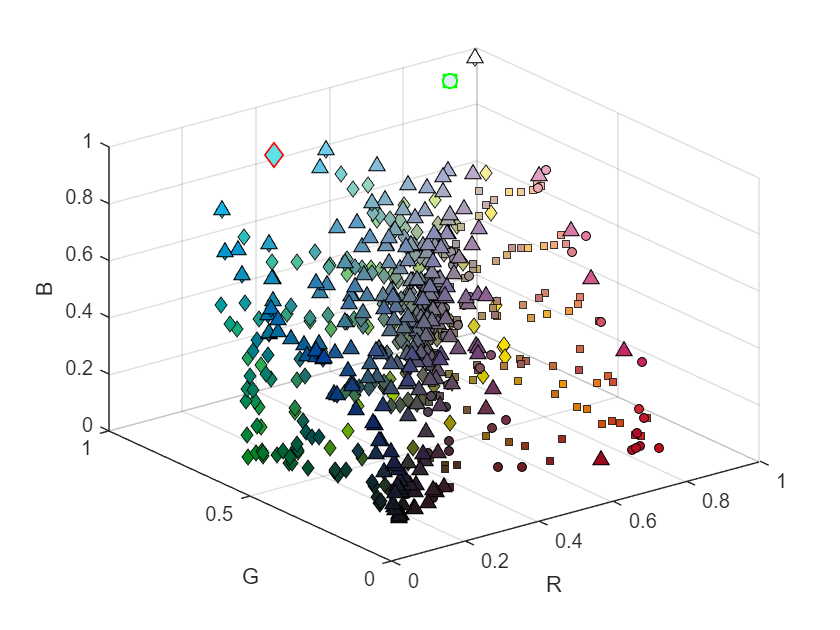


show3d = true;
if show3d
    figure;
    markers = {'o','s','d','^'};
    markersizes = {20,20,30,50};

%     i = cls;
%     Y = Ycell{i}; %RGB
%     W = Wcell{i}; %props
%     scatter3(W(:,1),W(:,2),W(:,3),markersizes{i},Y,markers{i},'filled','MarkerEdgeColor','k'); hold on
%     xlabel('a');
%     ylabel('b');
%     zlabel('c');
%     scatter3(props(1),props(2),props(3),70,rgbcol,'d','filled','MarkerEdgeColor','r','LineWidth',1);


    for i = 1:4
        Y = Ycell{i}; %RGB
        scatter3(Y(:,1),Y(:,2),Y(:,3),markersizes{i},Y,markers{i},'filled','MarkerEdgeColor','k'); hold on
    end
    xlabel('R');
    ylabel('G');
    zlabel('B');

    scatter3(rgbcol(1),rgbcol(2),rgbcol(3),70,rgbcol,'s','filled','MarkerEdgeColor','g','LineWidth',1);
    scatter3(rgbnew(1),rgbnew(2),rgbnew(3),50,rgbnew,'o','filled','MarkerEdgeColor','g','LineWidth',1);
    scatter3(rgb2(1),rgb2(2),rgb2(3),70,rgb2,'d','filled','MarkerEdgeColor','r','LineWidth',1);

end